A script to find the fitness of an organism in a chemostat.

The organism secretes cellulase, which must degrade the cellulose in the media into glucose. At the same time, the contents of the bioreactor are continuously being diluted with fresh media, and old media is allowed to flow out.

TODO:

- change initial media recipe to reflect an actual medium

Motivation:

Say we have an industrial bioreactor, and we want to engineer an organism to maximize the rate at which it converts solubilized cellulose into biofuel precursors. In this test, we are attempting to determine the ideal rate of enzyme production so that the critical growth rate (and by extension the total biomass, and the production rate of metabolic products) is maximized.

%%SCRIPT CONTROL VARIABLES
refreshmodel = true;
runalphamodels = true;
runO2models = true;
runNmodels = true;

%%STRATEGY VARIABLES
v.defaultbound = 10; %default exchange upper bound
%v.maxEnzymeRate = 1; %maximum enzyme:biomass ratio by weight for fixed production. 1:1 w/ alpha=1 should mean half of all amino acids go into enzyme
v.alpha = 0.1; %fixed percentage of the maximum enzyme rate being expressed

%%ENZYME VARIABLES. See https://www.brenda-enzymes.org/enzyme.php?ecno=3.2.1.4
%values used: wild-type T.ressei on 4-methylumbelliferyl cellobioside. https://www.brenda-enzymes.org/literature.php?e=3.2.1.4&r=737187
v.kcat_cel = 0.01; %mmol converted / mmol enzyme / second  %TODO: Confirm units
v.km_cel = 0.125; %Units = mmoles/cm^3

%%Glucose variables
v.km_glc = 0.01; %millimoles/cm^3.
v.vmax_glc = 10;
v.glcpercellulose = 218.2;%how many units of glucose get released per unit cellulose? 1:1 assumes units are by weight
    %Avicel degree of polymerization cite : https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3217711/
%v.biomassperglc = 1/(1.447e9); %how many units of biomass are produced for every unit glc consumed?
    %weight of E coli / weight of glc molecule = 433fg / (2.992e-22g) = 4.33e-13 / (2.992e-22) = 1.447e9
v.glcuptakerate = -10; %bound for the GLC import reaction
                         %This should be higher than required for max enzyme production

%Enzyme variables v 2- set high to check that everything works OK
%v.kat = 100;
%v.km = 0.0001;

%%WORLD/LAYOUT VARIABLES
%v.dilutionrate = 1/24; %fraction of media replaced per hour
v.dilutionrate = 1/12; %fraction of media replaced per hour
v.xdim = 1;
v.ydim = 1;
v.diff_cel = 0; %Diffusion constants
v.diff_enz = 1e-6; %Default is 1e-6;
v.diff_glc = 1e-6;
%v.enzdecayrate = 0; %degradation of enzyme over time
%v.deathrate = 0;
%v.enzymeperglc = 0.05; %how many units of enzyme are produced for every unit glc consumed?
v.initcellulose = 1;
v.initglc = 1e-8; %needed to bootstrap production
v.initmedia = 1; %amount of all other media added
v.initbiomass = 1e-3;
v.initO2 = 1; %oxygen level in the media
v.initNH4 = 1; %ammonium level in the media

%%COMETS EXECUTION VARIABLES
v.maxcycles = 600;
v.timestep = 1; %1/(60*60); %1/3600 hours = 1 second. 
v.filepath = 'C:\sync\biomes\cellulose\optima\temp';
v.writemedialog = true;
v.writebiomasslog = true;
v.writefluxlog = false;
v.lograte = 1;
v.maxspacebiomass = 1000;
v.spaceWidth = 10^(1/3);
v.lograte = 1;

v_default = v;

%%DEFAULT MODEL
if refreshmodel
    %model_default = load('C:\sync\biomes\models\ecoli_core_model_norm.mat'); %model with metabolite names normalized
    model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
    model_default = model_default.iJO1366;
end

%Run a variety of alphas
%alphas = [0.5:0.05:0.8 0.9:0.1:1.6];
%alphas = .5;
%alphas = [.01 .1 .5 1];
%alphas = [.01 .05 .1 .25 .5 .75 1 1.25 1.5];
%alphas = .02:.02:.2;
alphas = [0.025 0.035 0.05 0.1];
%alphas = 0.05;
models = cell(length(alphas),1);
for i=1:length(alphas)
a = alphas(i);
    v.alpha = a;
    mname = ['a = ' num2str(a)];
    model = buildEcoliModel(v,model_default,mname,'p');
    models{i} = model;
end
if runalphamodels
    newmodels = cell(length(models),1);
    for i = 1:length(models)
        newmodels{i} = runInChemostat(models{i});
    end
    models = newmodels;
end

%Plotting
plotBiomassOverTime(models);

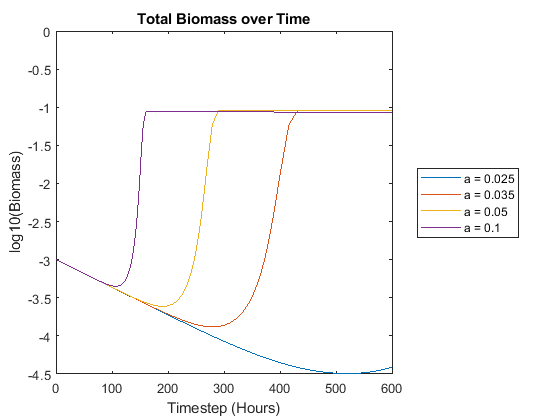

ylim([-4.5 0]);

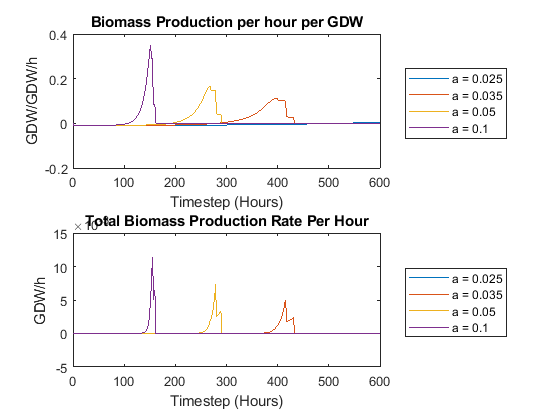


plotGrowthRates(models);

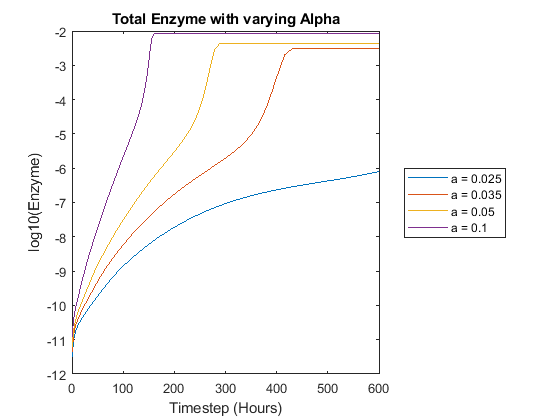

plotEnzymeTimecourse(models);

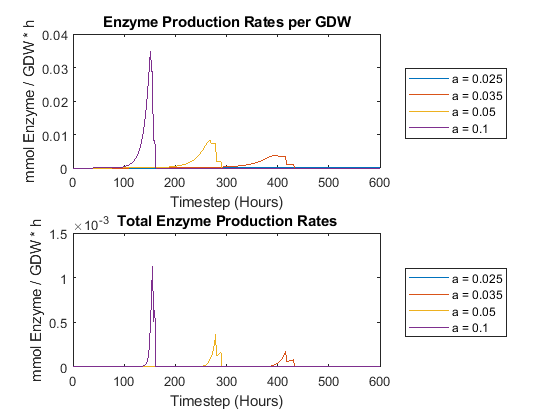

plotEnzRates(models);

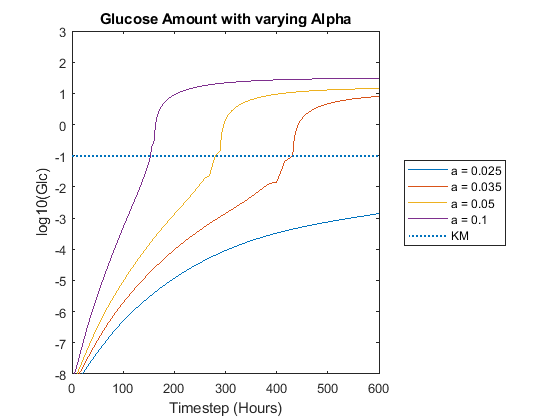

plotGlucoseTimecourse(models);
ylim([-8 3]);

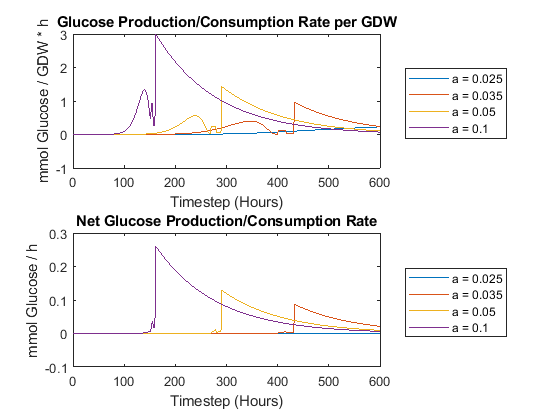

plotGlcRates(models);

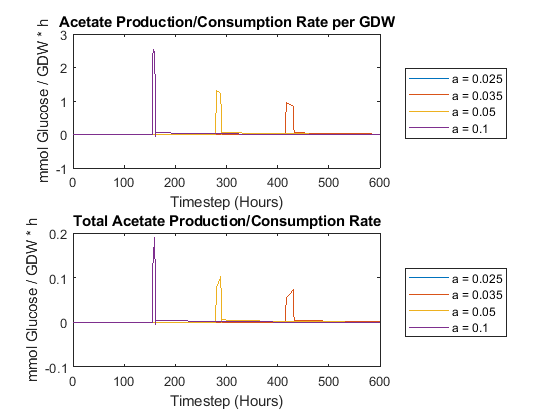

%plotCelluloseTimecourse(models);
plotAcetateRates(models);

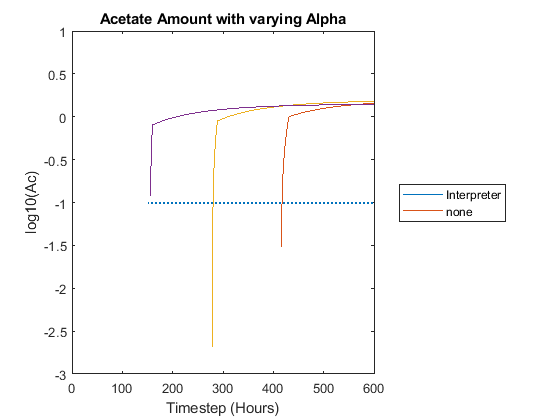

plotAcetateTimecourse(models);
ylim([-3 1])
xlim([0 600])

## Part II: Phases of Growth

This section explores what's up with the multi-phasic growth patterns seen above. Is there a diauxic shift, maybe some product that goes from being waste to a secondary carbon source?

The first step is to look for metabolites which increase then decrease in concentration.

media = parseMediaLog([models{end}.v.filepath '\log_media.m']);
nmets = max(media.met);
peakt = zeros(nmets,1); %timestep of the peak amount
maxamt = zeros(nmets,1);
for i = 1:nmets
    metrows = media(media.met == i,:);
    maxamt(i) = max(metrows.amt);
    maxloc = find((metrows.amt == max(metrows.amt)) & (metrows.amt > 0));
    if maxloc > 1 & maxloc < size(metrows,1)
        peakt(i) = metrows.t(maxloc);
    end
end


metnames = unique(media.metname);
peakmets = metnames(peakt > 0); %these are the metabolites which go up then down
peaktab = table(peakmets,peakt(peakt > 0),maxamt(peakt > 0));
peaktab.Properties.VariableNames = {'met' 'peak_time' 'peak_amt'}

peaktab = 6×3 table
       met        peak_time     peak_amt 
    __________    _________    __________

    'co2_e'       156               2.053
    'etoh_e'      160             0.62238
    'h2o_e'       161              3.7614
    'lac__D_e'    161             0.24183
    'no_e'         54          7.4504e-06
    'sulfac_e'    156           4.945e-06


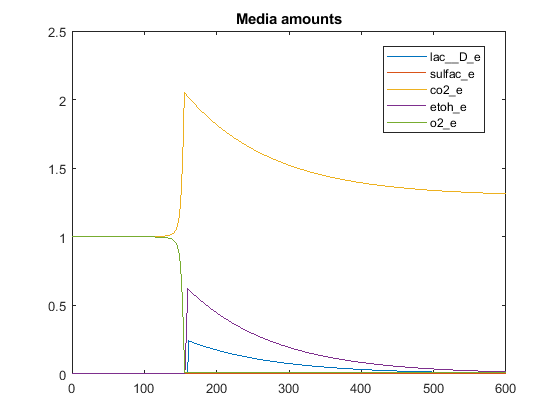


%looks like the metabolites of interest are D-lactate and sulfoacetate (lac__D_e and sulfac_e)
plotMediaTimecourse(media,{'lac__D_e' 'sulfac_e' 'co2_e' 'etoh_e' 'o2_e'});
title('Media amounts');

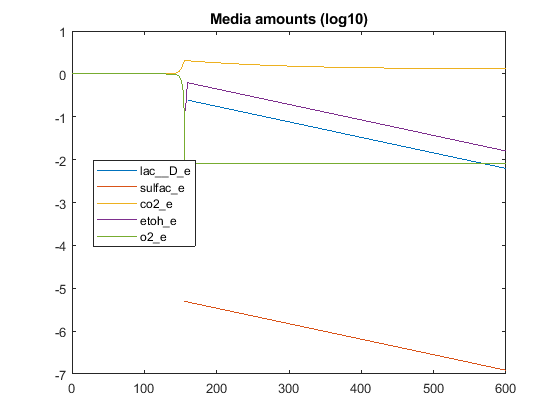

plotMediaTimecourse(media,{'lac__D_e' 'sulfac_e' 'co2_e' 'etoh_e' 'o2_e'},true);
title('Media amounts (log10)');

%there's practically no solfoacetate, so it looks like lactate is the culprit.
%Why does lactate spike so quickly?
%media(strcmp('lac__D_e',media.metname),:)

Lactate spikes up by ~.25 moles in a single timestep. 

Next: try without O2, and with increased O2

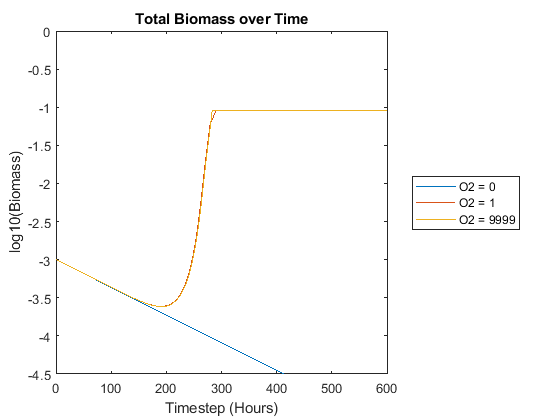

model1 = models{3};
model1.description = 'O2 = 1';
model2 = model1;
model2.v.initO2 = 0;
model2.description = 'O2 = 0';
model3 = model1;
model3.v.initO2 = 9999;
model3.description = 'O2 = 9999';
o2models = {model2 model1 model3};
if runO2models
    newmodels = cell(length(o2models),1);
    for i = 1:length(o2models)
        newmodels{i} = runInChemostat(o2models{i});
    end
    o2models = newmodels;
end

%Plotting
plotBiomassOverTime(o2models);
ylim([-4.5 0]);

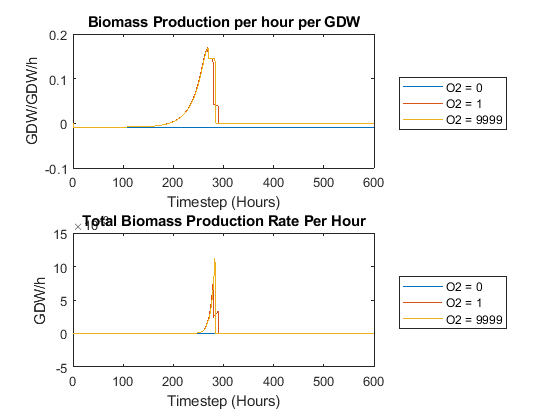


plotGrowthRates(o2models);

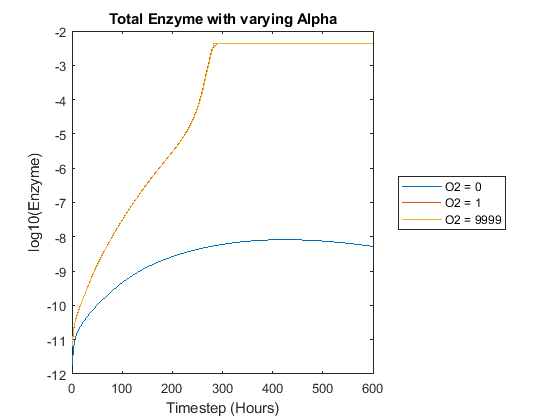

plotEnzymeTimecourse(o2models);

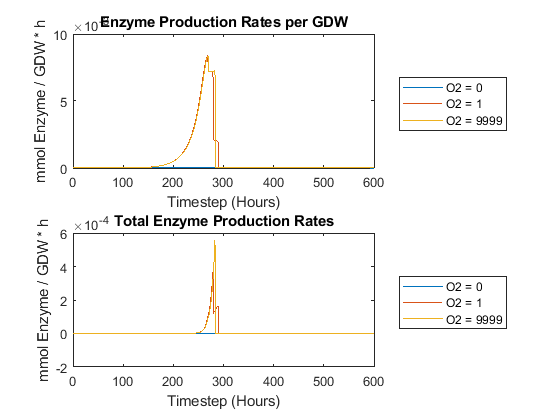

plotEnzRates(o2models);

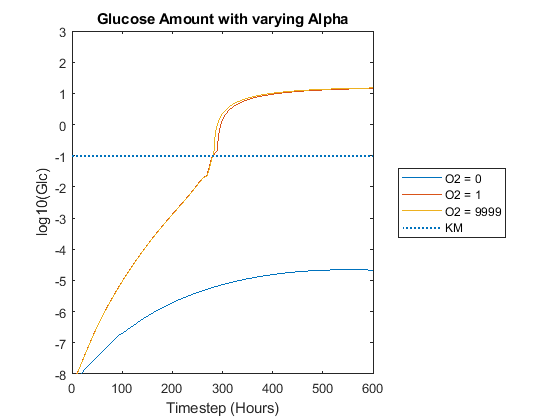

plotGlucoseTimecourse(o2models);
ylim([-8 3]);

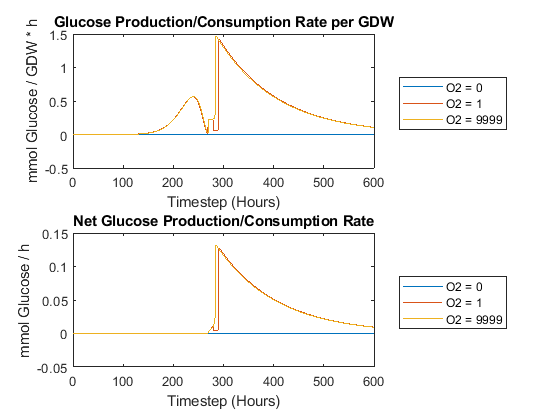

plotGlcRates(o2models);

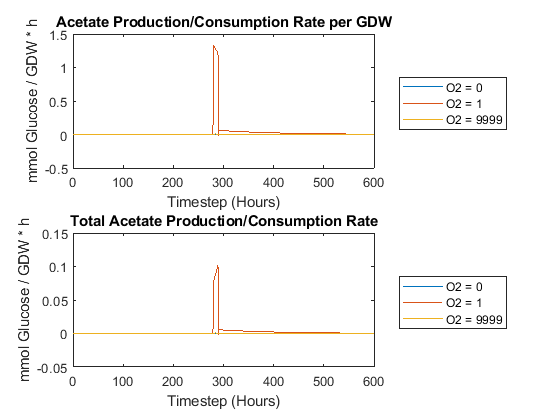

%plotCelluloseTimecourse(o2models);
plotAcetateRates(o2models);

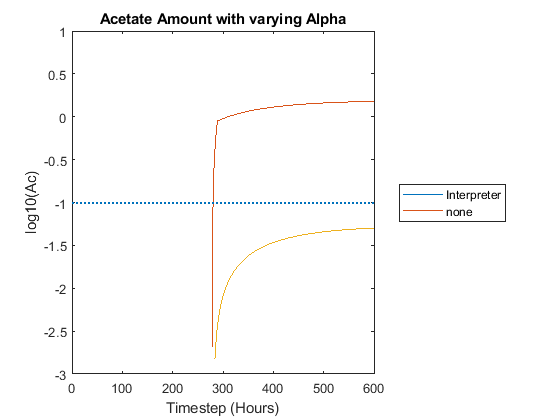

plotAcetateTimecourse(o2models);
ylim([-3 1])

media = parseMediaLog([o2models{end}.v.filepath '\log_media.m']);
nmets = max(media.met);
peakt = zeros(nmets,1); %timestep of the peak amount
maxamt = zeros(nmets,1);
for i = 1:nmets
    metrows = media(media.met == i,:);
    maxamt(i) = max(metrows.amt);
    maxloc = find((metrows.amt == max(metrows.amt)) & (metrows.amt > 0));
    if maxloc > 1 & maxloc < size(metrows,1)
        peakt(i) = metrows.t(maxloc);
    end
end


metnames = unique(media.metname);
peakmets = metnames(peakt > 0); %these are the metabolites which go up then down
peaktab = table(peakmets,peakt(peakt > 0),maxamt(peakt > 0));
peaktab.Properties.VariableNames = {'met' 'peak_time' 'peak_amt'}

peaktab = 5×3 table
       met       peak_time     peak_amt 
    _________    _________    __________

    'co2_e'      284              2.7205
    'cu_e'        91          3.4676e-06
    'h2o_e'      284              5.1127
    'so3_e'       38          1.0369e-07
    'tcynt_e'     38          1.0369e-07


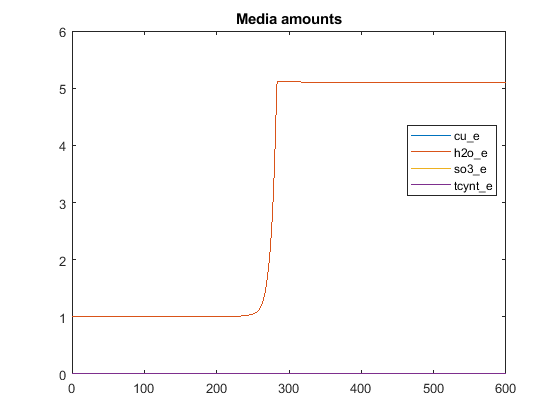


plotMediaTimecourse(media,{'cu_e' 'h2o_e' 'so3_e' 'tcynt_e'});
title('Media amounts');

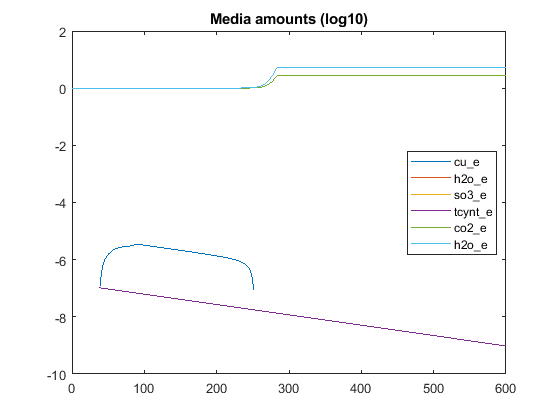

plotMediaTimecourse(media,{'cu_e' 'h2o_e' 'so3_e' 'tcynt_e' 'co2_e' 'h2o_e'},true);
title('Media amounts (log10)');

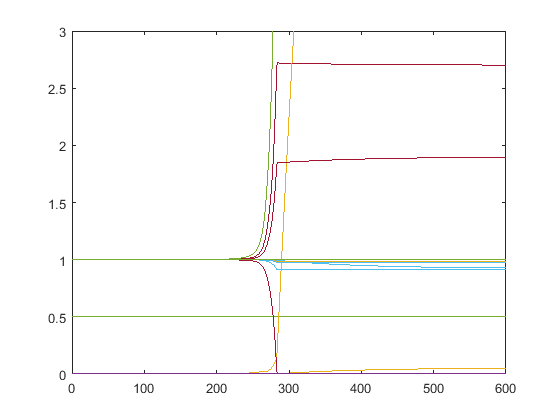


plotMediaTimecourse(media,unique(media.metname));
legend(gca,'off'); %hide legend
ylim([0 3]);

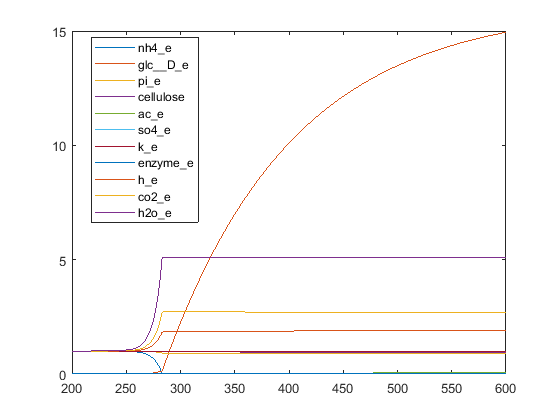

%interesting curves are {nh4_e, glc__D_e, pi_e, cellulose, ac_e, so4_e, k_e, enzyme_e, h_e, co2_e, h2o_e}
plotMediaTimecourse(media,{'nh4_e', 'glc__D_e', 'pi_e', 'cellulose', 'ac_e', 'so4_e', 'k_e', 'enzyme_e', 'h_e', 'co2_e', 'h2o_e'});
xlim([200,600]);

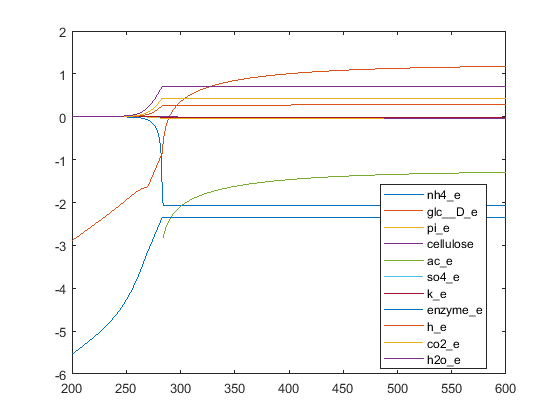

plotMediaTimecourse(media,{'nh4_e', 'glc__D_e', 'pi_e', 'cellulose', 'ac_e', 'so4_e', 'k_e', 'enzyme_e', 'h_e', 'co2_e', 'h2o_e'},true);
xlim([200,600]);

%media(strcmp('lac__D_e',media.metname),:)

In the above, NH4 drops to zero. Growth is N limited?

Create layouts with different NH4 concentrations in the media and compare biomass

nmodel1 = models{3};
nmodel1.description = 'NH4 = 1';
nmodel2 = nmodel1;
nmodel2.v.initNH4 = 0;
nmodel2.description = 'NH4 = 0';
nmodel3 = nmodel1;
nmodel3.v.initNH4 = 9999;
nmodel3.description = 'NH4 = 9999';
nmodels = {nmodel2 nmodel1 nmodel3};
if runNmodels
    newmodels = cell(length(nmodels),1);
    for i = 1:length(nmodels)
        newmodels{i} = runInChemostat(nmodels{i});
    end
    nmodels = newmodels;
end

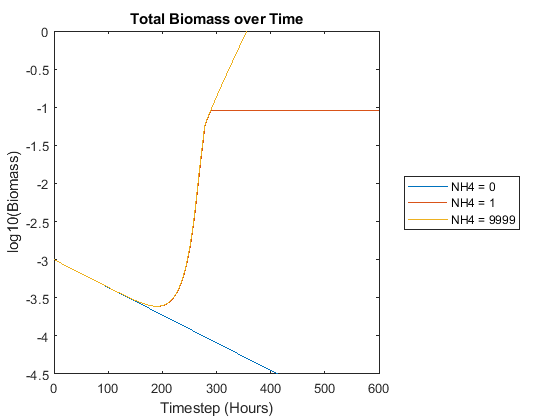


%Plotting
plotBiomassOverTime(nmodels);
ylim([-4.5 0]);

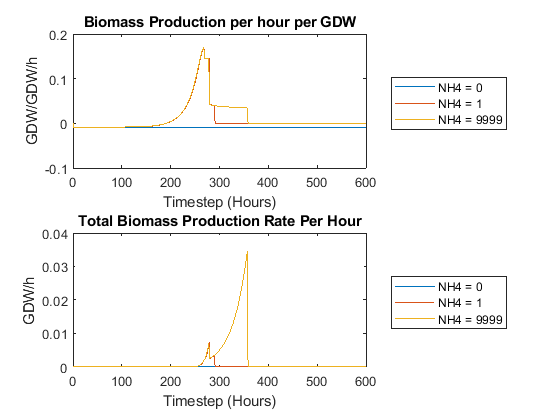

plotGrowthRates(nmodels);

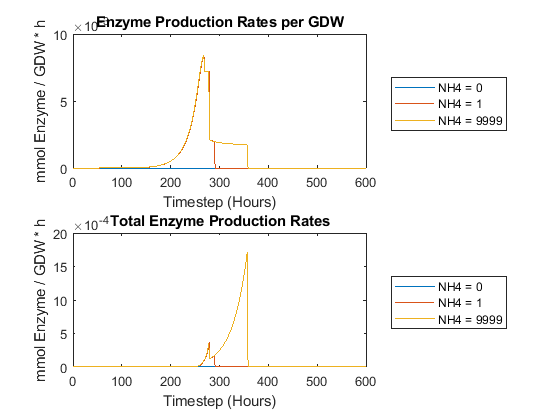

plotEnzRates(nmodels);

Now run a model with increased N and O

model = models{3};
model.v.initO2 = 999;
model.v.initNH4 = 999;
model.description = 'NH4,O2 = 999';
model = runInChemostat(model);
media = parseMediaLog([model.v.filepath '\log_media.m']);

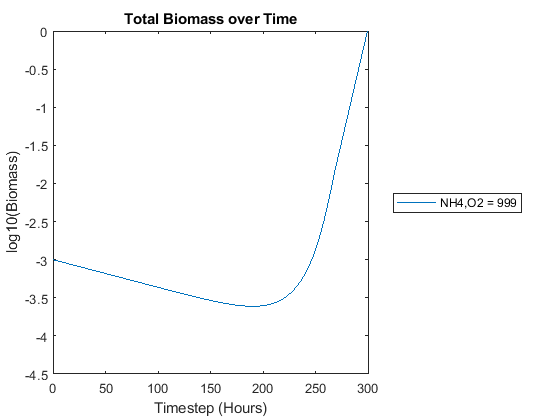

plotBiomassOverTime({model});
ylim([-4.5 0]);

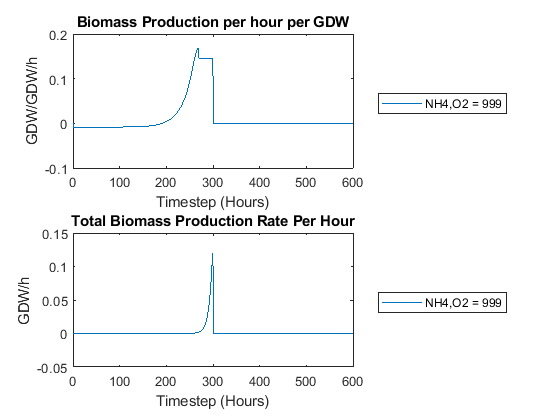

plotGrowthRates({model});

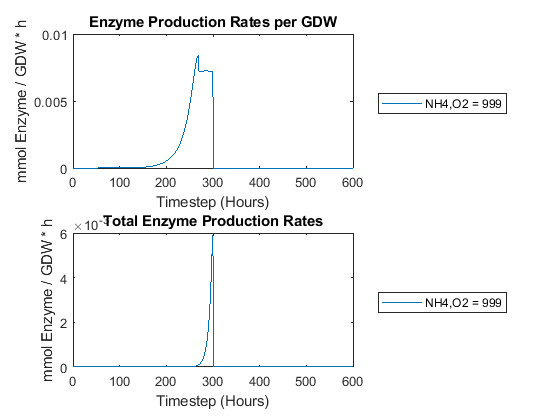

plotEnzRates({model});

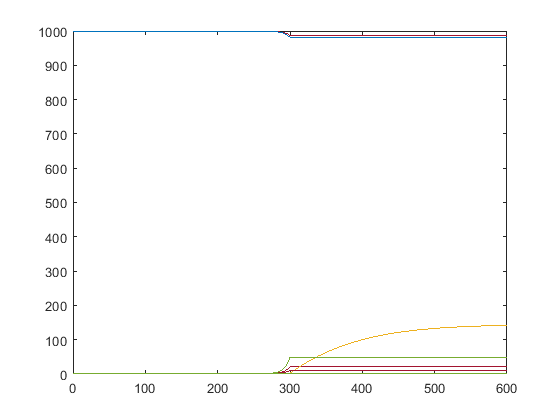

figure();
p = plotMediaTimecourse(media,unique(media.metname));
legend(gca,'off');

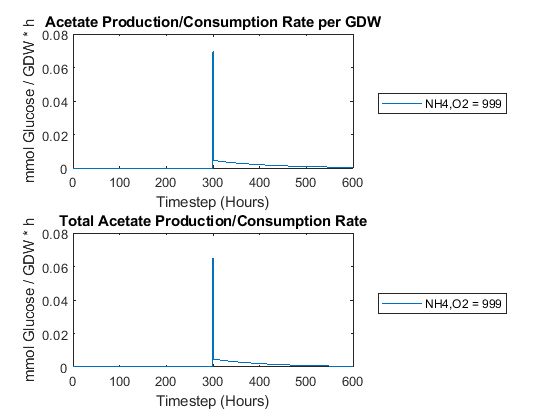

plotAcetateRates({model});

**Try the increased O2/NH4 model with an increased upper limit for Glc uptake**

gv = model.v;
gv.vmax_glc = 100;
gv.glcuptakerate = -100;
%gv.initO2 = 999;
%gv.initNH4 = 999;
gmodel = buildEcoliModel(gv,model_default,'NH4,O2=999,vGlc=100','p');
gmodel = runInChemostat(gmodel);
gmedia = parseMediaLog([gmodel.v.filepath '\log_media.m']);

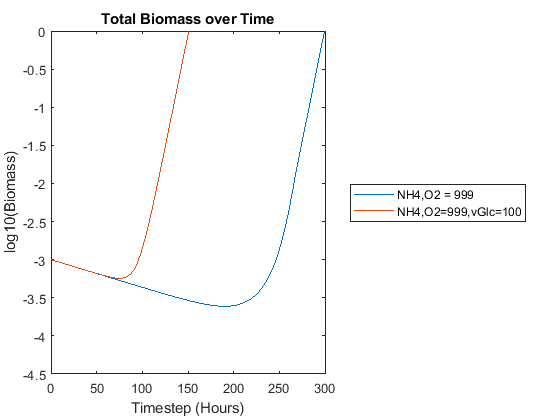

plotBiomassOverTime({model gmodel});
ylim([-4.5 0]);

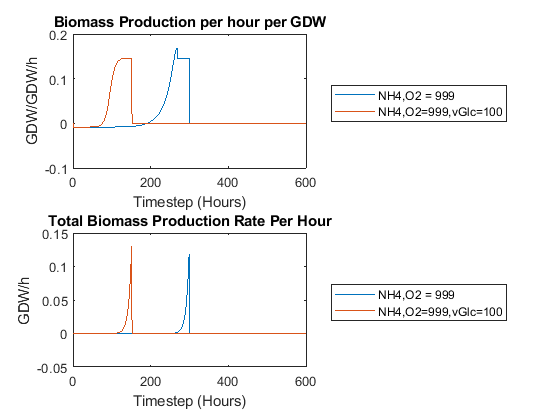

plotGrowthRates({model gmodel});

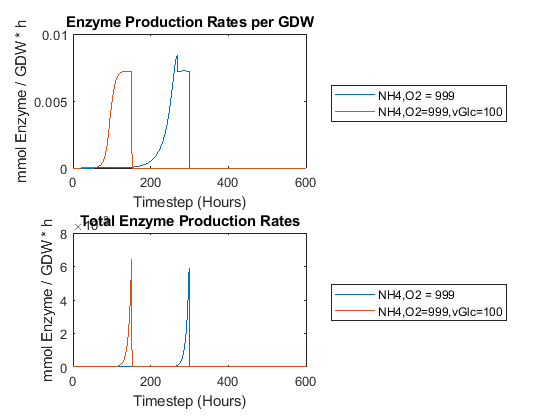

plotEnzRates({model gmodel});

figure();
p = plotMediaTimecourse(media,unique(media.metname));
legend(gca,'off');

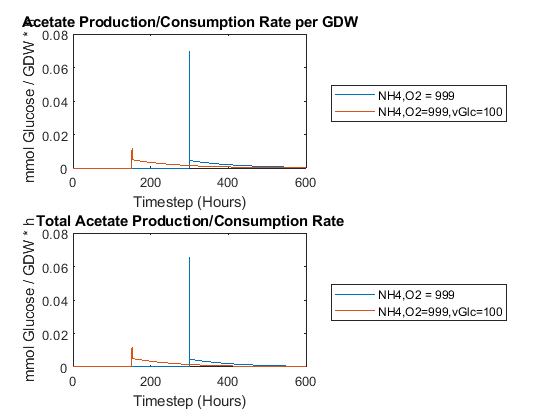

plotAcetateRates({model gmodel});

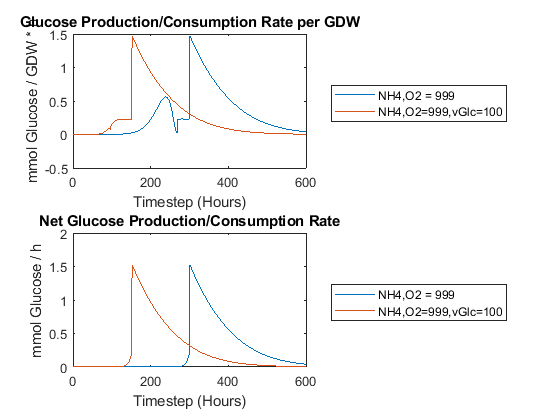

plotGlcRates({model gmodel});

function model = runInChemostat(model)
layout = buildCelOptLayout(model);
layout = setInitialMedia(layout,'o2_e',model.v.initO2);
layout = setInitialMedia(layout,'nh4_e',model.v.initNH4);
layout.initial_pop = model.v.initbiomass;
layout = makeChemostat(layout,'flowPerH',model.v.dilutionrate,'volume',model.v.spaceWidth^3);


createCometsFiles(layout,model.v.filepath,'layout_temp.txt');
runCometsOnDirectory(model.v.filepath);

tab = parseBiomassLog([model.v.filepath '\log_biomass.m']);
model.biomass = tab.biomass; %no need to sum if there's no biomass diffusion
model.timestep = tab.t;

if model.v.writemedialog
    media = parseMediaLog([model.v.filepath '\log_media.m'],{'enzyme_e', 'cellulose', 'glc__D_e', 'ac_e'});
    model.enzyme_amt = zeros(length(model.timestep),1);
    model.cellulose_amt = zeros(length(model.timestep),1);
    model.glc_amt = zeros(length(model.timestep),1);
    model.acetate_amt = zeros(length(model.timestep),1);
    for i = 1:length(model.timestep)
        time = model.timestep(i);
        enzrows = (media.t == time) & strcmp(media.metname,'enzyme_e');
        celrows = (media.t == time) & strcmp(media.metname,'cellulose');
        glcrows = (media.t == time) & strcmp(media.metname,'glc__D_e');
        acrows = (media.t == time) & strcmp(media.metname,'ac_e');
        subtab = media(enzrows,:);
        model.enzyme_amt(i) = sum(subtab.amt);
        subtab = media(celrows,:);
        model.cellulose_amt(i) = sum(subtab.amt);
        subtab = media(glcrows,:);
        model.glc_amt(i) = sum(subtab.amt);
        subtab = media(acrows,:);
        model.acetate_amt(i) = sum(subtab.amt);
    end
end

end